% we are gonna write the algorithm
% this is from matlab

%iniitial setup
n_nodes = 11;
n_data = 10;
alpha = 0.1;
beta = 0.1;

L = optimvar('L',n_nodes,n_nodes);
Y = optimvar('Y',n_nodes,n_data);
prob = optimproblem;

f = @(L)trace(L);

%set the objective function
prob.Objective = fcn2optimexpr(f, L);

## test the duplication matrix

test = full(DuplicationM(2))

vech = [1 2 3]';

## Optimize the half vectorized L

optimization problem equation 17

%iniitial setup
n_nodes = 11;
n_data = 10;
alpha = 0.1;
beta = 0.1;

M = DuplicationM(n_nodes);

vechL = optimvar('vechL',n_nodes * (n_nodes + 1) / 2, 1);

%objective
prob = optimproblem;
prob.Objective = fcn2optimexpr(@optimize_vechL,vechL,Y,alpha,beta,'OutputSize',[1,1]);

%first tr(L) = n
expr_1 = @(vechL,M,n_nodes)trace(reshape(M * vechL, n_nodes,n_nodes));
optimization_cond_1 = fcn2optimexpr(expr_1,vechL,M,n_nodes);
prob.Constraints.const1 = optimization_cond_1 == n_nodes;

%second Lij  = Lji <= 0, non diagnal elements of the lower triangular
%matrix are smaller than 0
optimization_cond_2 = fcn2optimexpr(@cal_non_diag,vechL,n_nodes);
prob.Constraints.const2 = optimization_cond_2 <= zeros(n_nodes*(n_nodes-1)/2,1);

%third constraint: sum of each row is 0
expr_3 = @(vechL,n_nodes) reshape(M * vechL, n_nodes,n_nodes) * ones(n_nodes,1);
optimization_cond_3 = fcn2optimexpr(expr_3,vechL,n_nodes);

prob.Constraints.const3 = optimization_cond_3 == zeros(n_nodes,1);

## Optimize the Y matrix

Y = optimvar('Y',n_nodes,n_data);
prob2 = optimproblem;
prob2.Objective = fcn2optimexpr(@optimize_Y,Y,alpha,L,'OutputSize',[1,1]);


there you go, this is all we need to do for this task. Then we can dive into the actual optimization. 

## Graph Learning for Smooth Signal Representation (GL-SigRep)

num_iter = 5; % number of max iterations
%iniitial setup

alpha = 1;
beta = 1;

n_nodes = 30;
%first 61 electrodes for now
X_test = a_coefficients_electrodes(1:n_nodes,:);
Y0 = X_test;

n_data = size(X_test,2);

M = full(DuplicationM(n_nodes));

%initialize parameters
Y = Y0;
vechL_0.vechL = ones(n_nodes * (n_nodes + 1) / 2, 1);
Y_0.Y_opt = zeros([n_nodes,n_data]);

[L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.500000e+04.

Finished 1 iteration with 2.04  and 1.11
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
opti

toc

Elapsed time is 38.945271 seconds.


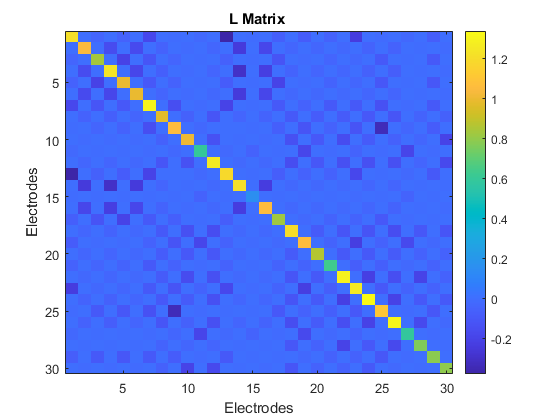

imagesc(L_iter)
title('L Matrix ')
xlabel('Electrodes')
ylabel('Electrodes')
colorbar    

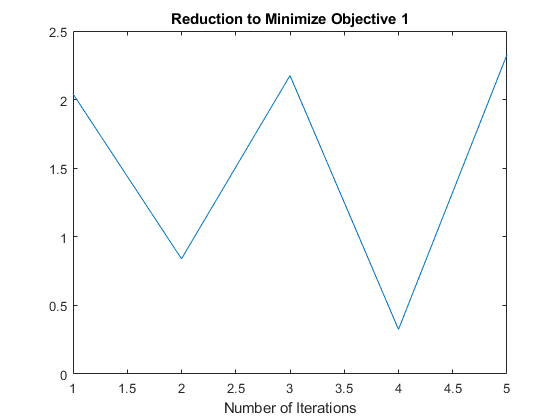

figure
plot(vechl_result)
xlabel('Number of Iterations')
title('Reduction to Minimize Objective 1')


alpha = 30;
[vechl_result, L_iter] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>
Finished 1 iteration with 1.68  and 0.71
Solving problem using fmincon.

<a href = "

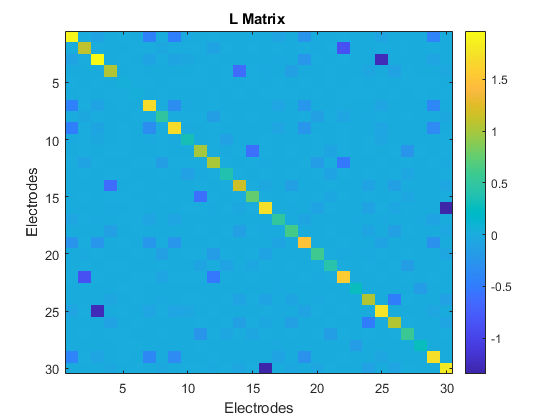

figure
imagesc(L_iter)
title('L Matrix ')
xlabel('Electrodes')
ylabel('Electrodes')
colorbar

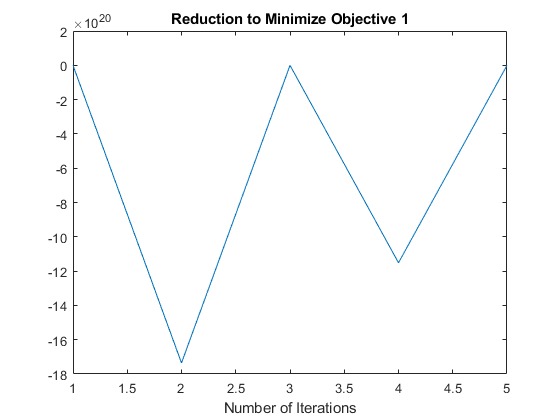


figure
plot(vechl_result)
xlabel('Number of Iterations')
title('Reduction to Minimize Objective 1')

% creating a ground truth model
n_nodes = 30;
num_iter = 3; % number of max iterations

network_1_value = 5;
network_2_value = 8;

network_1 = [1 2 3 4 5];
network_2 = [9 12 13 14];
X_test = randn(n_nodes,1) / 3;

X_test_temp = zeros(n_nodes,1);
X_test_temp(network_1) = network_1_value;
X_test_temp(network_2) = network_2_value;
X_test = X_test + X_test_temp;

Y0 = X_test;

n_data = size(X_test,2);

M = full(DuplicationM(n_nodes));

%initialize parameters
Y = Y0;
Y_0.Y_opt = zeros([n_nodes,n_data]);
vechL_0.vechL = zeros(n_nodes * (n_nodes + 1) / 2, 1);

alpha = 2;

[L_iter,Y,vechl_result,Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Problem appears unbounded.

fminunc stopped because the objective function value is less than
or equal to the value of the objective function limit.

<stopping criteria details>
Finished 1 iteration with -774467334479846703104.00  and -774467334444542984192.00
Solving problem using fminco

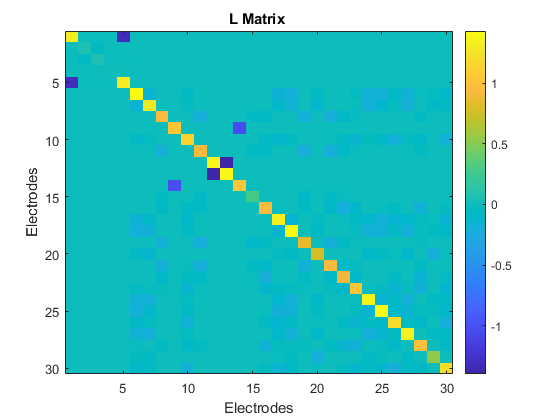

figure
imagesc(L_iter)
title('L Matrix ')
xlabel('Electrodes')
ylabel('Electrodes')
colorbar

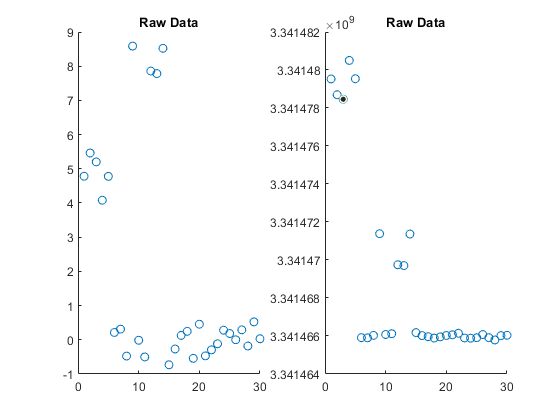

figure
subplot(1,2,1)
scatter(1:length(X_test),X_test)
title('Raw Data')

subplot(1,2,2)
scatter(1:length(Y),Y)
title('Denoised Data')

%then we look at spectral decomposition
[V,D] = eig(L_iter)
figure
imagesc(V)


This is somewhat working. We have some neighborhoods of correlated signal, one with the small neigiborhoods and the larger connected component in this matrix.  The problems are

- The algorithm is somewhat working. We can demonstrate the usage of graph search 

% function [L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0)
% tic
% for iter_i = 1:num_iter
%     
%     %optimize L
%     vechL = optimvar('vechL', n_nodes * (n_nodes + 1) / 2, 1);
%     
%     prob = optimproblem;
%     prob.Objective = fcn2optimexpr(@optimize_vechL,vechL,Y,M,alpha,beta,'OutputSize',[1,1]);
%     
%     %first tr(L) = n
%     expr_1 = @(vechL,M,n_nodes)trace(reshape(M * vechL, n_nodes,n_nodes));
%     optimization_cond_1 = fcn2optimexpr(expr_1,vechL,M,n_nodes);
%     prob.Constraints.const1 = optimization_cond_1 == n_nodes;
%     
%     %second Lij  = Lji <= 0, non diagnal elements of the lower triangular
%     %matrix are smaller than 0
%     optimization_cond_2 = fcn2optimexpr(@cal_non_diag,vechL,n_nodes) <= zeros(n_nodes*(n_nodes-1)/2,1);
%     prob.Constraints.const2 = optimization_cond_2 ;
%     
%     %third constraint: sum of each row is 0
%     expr_3 = @(vechL,n_nodes) reshape(M * vechL, n_nodes,n_nodes) * ones(n_nodes,1);
%     optimization_cond_3 = fcn2optimexpr(expr_3,vechL,n_nodes); 
%     prob.Constraints.const3 = optimization_cond_3 == zeros(n_nodes,1);
%     
%     solution = solve(prob,vechL_0); %solve the problem
%     L_iter = reshape(M * solution.vechL,n_nodes,n_nodes);
%     
%     %second part of the problem is to optimize L_iter
%     Y_opt = optimvar('Y_opt',n_nodes,n_data);
%     prob2 = optimproblem;
%     prob2.Objective = fcn2optimexpr(@optimize_Y,Y_opt,X_test,L_iter,alpha,'OutputSize',[1,1]);
%     
%     %initialize the problem
%     solution2 = solve(prob2,Y_0); %solve the problem
%     
%     
%     %update Y for next round
%     vechL_0.vechL = solution.vechL;
%     Y = solution2.Y_opt;
%     Y_0.Y_opt = Y;
%     
%     %save the results
%     vechl_result(iter_i) = optimize_vechL(solution.vechL,Y,M,alpha, beta);
%     Y_result(iter_i) = optimize_Y(Y,X_test,L_iter,alpha);
%     
%     fprintf('Finished %d iteration with %0.2f  and %0.2f',iter_i,vechl_result(iter_i),Y_result(iter_i))
%     
% end
% end

Pretending that we have a complete L matrix.  Then we can look at its 